# Solving First order Linear ODE with Dirichlet BCs using Least Square Method

Sagar Bodkhe

May 2020

______________________________________________________________________________

We consider this problem:

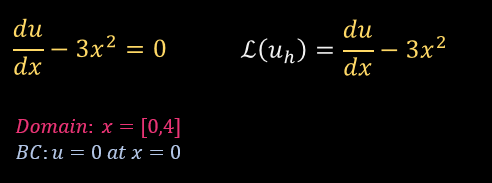

**Note:** this problem has only dirichlet boundary conditions.

%% Initialization
close all;
syms psi(x)
syms R(c1,x)

Select basis function and construct trial solution.

i=3;

%% Basis function, Residual and Rnorm 

psi(x) = x^i;
uh(c1,x) = c1*psi;
R(c1,x)= diff(uh,x) - 3*x^2;
Rnorm = int(R*R, x,[0 4]);


Minimize the residual norm and solve for c

%% Minimizing Rnorm w.r.t c1
eqn = diff(Rnorm,c1)==0;
c =solve(eqn,c1);
uh(x) = uh(c,x);

%% Domain for plotting
x0=linspace(0,4,50);


Plots

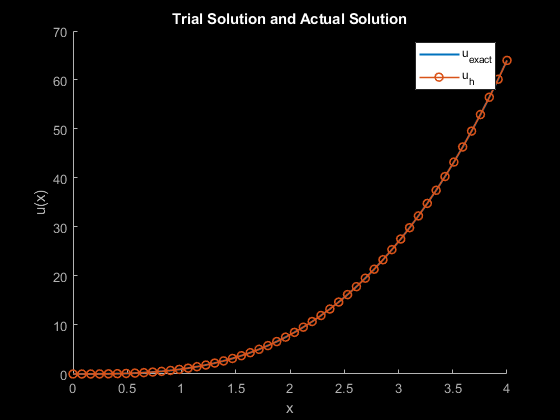

%% Plots

figure(1)
hold on;
plot(x0,uh(x0),'linewidth',1.5) % Trial Solution
plot(x0,x0.^3,'-o','linewidth',1.2); %Exact Sol
title("Trial Solution and Actual Solution",'Color', 'white');
legend('u_{exact}','u_{h}');
xlabel("x");
ylabel("u(x)");
blackFig;

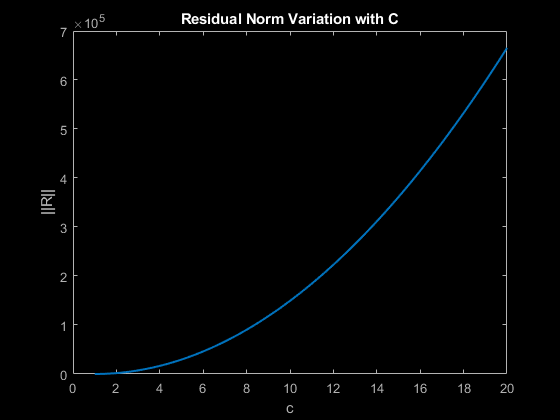


figure(2)
c0=linspace(1,20,100);
plot(c0,Rnorm(c0),'linewidth',1.5) % Rnorm
title("Residual Norm Variation with C",'Color', 'white');
xlabel("c");
ylabel("||R||");
blackFig;

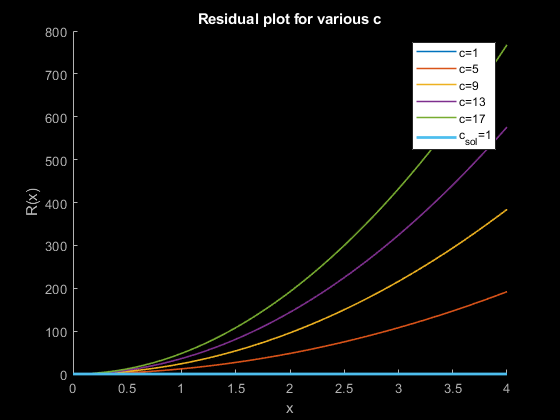


figure(3)
hold on;
ch=1:4:20;
legtext=cell(numel(ch),1);
for i=1:numel(ch)
   plot(x0, R(ch(i),x0),'linewidth',1.2)  % Residual    
   legtext{i} = "c=" + num2str(ch(i));   
end
plot(x0, R(c,x0),'linewidth',2)  % Residual 
title("Residual plot for various c",'Color', 'white');
xlabel("x");
ylabel("R(x)");
legend(legtext,"c_{sol}="+num2str(double(c)))
blackFig;

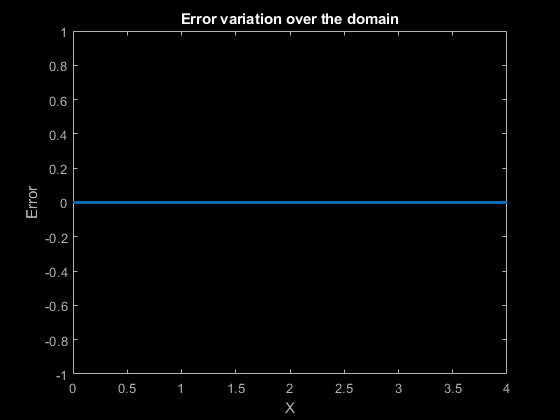


figure(4)
error= double(x0.^3 - uh(x0));
plot(x0,round(error,5),'LineWidth',2)
xlabel("X")
ylabel("Error")
title("Error variation over the domain",'color','white')
blackFig;

%% END

